# Decode Rate 3/4 LDPC Codewords

Initialize parameters for the prototype matrix and block size to configure a rate 3/4 LDPC code specified in IEEE® 802.11. Create the parity-check matrix by using the `ldpcQuasiCyclicMatrix` function.

%% 5G NR LDPC Simulation
clear
clc
close all

bgn = 1

bgn = 1

Z = 384

Z = 384


%% 计算基矩阵（HBG）
[HBG,rHBG,cHBG] = ldpc_01_HbMatrix_calc(bgn,Z);

%% 计算校验矩阵（H）及HBG2特殊位置，LDPC译码器控制字
[HMatrix,data_pos,data_spec] = ldpc_02_HMatrix_calc(HBG,Z);
[LDPC_N, LDPC_K, LDPC_P, LDPC_Q] = ldpc_02_Calc_decparam(bgn, Z);
[interweave_addr,barrel_shifter,variable_ctrl,check_ctrl, V] = ldpc_03_Calc_decparam(LDPC_N,LDPC_K,LDPC_P,LDPC_Q,HMatrix, Z);

pcmatrix = ldpcQuasiCyclicMatrix(Z,HBG);

Create LDPC encoder and decoder configuration objects, displaying their properties. 

cfgLDPCEnc = ldpcEncoderConfig(pcmatrix)

cfgLDPCEnc =   ldpcEncoderConfig - 属性:

     ParityCheckMatrix: [17664×26112 logical]

   Read-only properties:
           BlockLength: 26112
    NumInformationBits: 8448
    NumParityCheckBits: 17664
              CodeRate: 0.3235


%cfgLDPCDec = ldpcDecoderConfig(pcmatrix)
cfgLDPCDec = nr5g.internal.ldpc.getParams(bgn,Z);
algStr = {'bp','layered-bp','norm-min-sum','offset-min-sum'};

Transmit an LDPC-encoded, QPSK-modulated bit stream through an AWGN channel. Demodulate the signal, decode the received codewords, and then count bit errors. Use nested `for` loops to process multiple SNR settings and frames with and without LDPC forward error correction (FEC) coding of the transmitted data.

M = 4;
maxnumiter = 8;
% snr = [0.01 0.1 0.2 0.5 1 2 3 4 5 6 7 10 15 20];
snr = -2.0 : 0.1 : 2.0

snr =    -2.0000   -1.9000   -1.8000   -1.7000   -1.6000   -1.5000   -1.4000   -1.3000   -1.2000   -1.1000   -1.0000   -0.9000   -0.8000   -0.7000   -0.6000   -0.5000   -0.4000   -0.3000   -0.2000   -0.1000         0    0.1000    0.2000    0.3000    0.4000    0.5000    0.6000    0.7000    0.8000    0.9000    1.0000    1.1000    1.2000    1.3000    1.4000    1.5000    1.6000    1.7000    1.8000    1.9000    2.0000


numframes = 10 * ones(size(snr));
%numframes(snr >= -1 & snr <= 1) = 100;
%numframes(snr > 1) = 1000

qpskmod = comm.PSKModulator(M,'BitInput',true);
qpskmod2 = comm.PSKModulator(M);

ber_bp = comm.ErrorRate;
ber_noEnc = comm.ErrorRate;
ber_layered = comm.ErrorRate;
ber_nr_bp = comm.ErrorRate;
ber_nr_layered = comm.ErrorRate;
ber_my_nr_bp = comm.ErrorRate;
ber_my_nr_layered = comm.ErrorRate;

ber_bp_list = zeros(1, length(snr));
ber_layered_list = zeros(1, length(snr));
ber_nr_bp_list = zeros(1, length(snr));
ber_nr_layered_list = zeros(1, length(snr));
ber_my_nr_bp_list = zeros(1, length(snr));
ber_my_nr_layered_list = zeros(1, length(snr));

for ii = 1:length(snr)
    qpskdemod = comm.PSKDemodulator(M,'BitOutput',true, ...
        'DecisionMethod','Approximate log-likelihood ratio', ...
        'Variance',1/10^(snr(ii)/10));
    qpskdemod2 = comm.PSKDemodulator(M);

    currentNumFrames = numframes(ii);

    for counter = 1:currentNumFrames

        data = randi([0 1],cfgLDPCEnc.NumInformationBits,1,'int8');

        % Transmit and receive with LDPC coding
        encodedData = ldpcEncode(data,cfgLDPCEnc);
        modSignal = qpskmod(encodedData);
        receivedSignal = awgn(modSignal,snr(ii));
        demodSignal = qpskdemod(receivedSignal);

        nrEncodedData = nrLDPCEncode(data,bgn);
        nrModSignal = qpskmod(nrEncodedData);
        nrReceivedSignal = awgn(nrModSignal,snr(ii));
        nrDemodSignal = qpskdemod(nrReceivedSignal);

        % bp
        cfgLDPCDec.Algorithm = 'bp';
        receivedBits_bp = ldpcDecode(demodSignal,cfgLDPCDec,maxnumiter,'OutputFormat','info','DecisionType','hard','Termination','max');
        errStats_bp = ber_bp(data,receivedBits_bp);

        % nr bp
        receivedBits_nr_bp = nrLDPCDecode(nrDemodSignal, bgn, maxnumiter, 'Algorithm', 'Belief propagation' ,'OutputFormat','info','DecisionType','hard','Termination','max');
        errStats_nr_bp = ber_nr_bp(data, receivedBits_nr_bp);

        % layered-bp
        cfgLDPCDec.Algorithm = 'layered-bp';
        receivedBits_layered = ldpcDecode(demodSignal,cfgLDPCDec,maxnumiter,'OutputFormat','info','DecisionType','hard','Termination','max');
        errStats_layered = ber_layered(data,receivedBits_layered);

        % nr layered-bp
        receivedBits_nr_layered = nrLDPCDecode(nrDemodSignal, bgn, maxnumiter, 'Algorithm', 'Layered belief propagation' ,'OutputFormat','info','DecisionType','hard','Termination','max');
        errStats_nr_layered = ber_nr_layered(data, receivedBits_nr_layered);

        % Transmit and receive with no LDPC coding
        noCoding = qpskmod2(data);
        rxNoCoding = awgn(noCoding,snr(ii));
        rxBitsNoCoding = qpskdemod2(rxNoCoding);
        errStatsNoCoding = ber_noEnc(data,int8(rxBitsNoCoding));

        % my own decoder
        [N, C] = size(nrDemodSignal);
        typeIn = class(nrDemodSignal);
        myNrDemodSignal = [zeros(2*Z,C,typeIn); nrDemodSignal];
        myNrDemodSignal(myNrDemodSignal > 4) = 4;
        myNrDemodSignal(myNrDemodSignal < -4) = -4;
        llr_data = floor(myNrDemodSignal*2^4);
        writematrix(llr_data, 'llrIn.txt','Delimiter', ',');

        % bp
        [dec_data_flooding, llr_flooding] = ldpc_decoder_multrate_serial(llr_data,maxnumiter,LDPC_N,LDPC_K, LDPC_P, LDPC_Q,interweave_addr+1,barrel_shifter,variable_ctrl,check_ctrl, Z);
        writematrix(llr_flooding, 'llrOut_flooding.txt','Delimiter', ',');
        dec_data_flooding = int8(dec_data_flooding);
        errStats_my_nr_bp = ber_my_nr_bp(data,dec_data_flooding');
        % layered bp
        [dec_data_layered, llr_layered, it]  = ldpc_decoder_layered_02(llr_data, maxnumiter, HBG, HMatrix, check_ctrl, Z);
        writematrix(llr_layered, 'llrOut_layered.txt','Delimiter', ',');
        dec_data_layered = int8(dec_data_layered);
        errStats_my_nr_layered = ber_my_nr_layered(data,dec_data_layered');
    end
    fprintf(['SNR = %2d\n   Coded: Error rate = %1.2f, ' ...
        'Number of errors = %d\n'], ...
        snr(ii),errStats_bp(1),errStats_bp(2))
    fprintf(['SNR = %2d\n   Coded: Error rate = %1.2f, ' ...
        'Number of errors = %d\n'], ...
        snr(ii),errStats_layered(1),errStats_layered(2))
    %fprintf(['Noncoded: Error rate = %1.2f, ' ...
    %    'Number of errors = %d\n'], ...
    %    errStatsNoCoding(1),errStatsNoCoding(2))

    ber_bp_list(ii) = errStats_bp(1);
    ber_layered_list(ii) = errStats_layered(1);
    ber_nr_bp_list(ii) = errStats_nr_bp(1);
    ber_nr_layered_list(ii) = errStats_nr_layered(1);
    ber_my_nr_bp_list(ii) = errStats_my_nr_bp(1);
    ber_my_nr_layered_list(ii) = errStats_my_nr_layered(1);
    
    reset(ber_bp);
    reset(ber_nr_bp);
    reset(ber_noEnc);
    reset(ber_layered);
    reset(ber_nr_layered);
    reset(ber_my_nr_bp);
    reset(ber_my_nr_layered);
end

SNR = -2
   Coded: Error rate = 0.12, Number of errors = 10080


SNR = -2
   Coded: Error rate = 0.10, Number of errors = 8122


SNR = -1.900000e+00
   Coded: Error rate = 0.11, Number of errors = 9497


SNR = -1.900000e+00
   Coded: Error rate = 0.08, Number of errors = 7078


SNR = -1.800000e+00
   Coded: Error rate = 0.10, Number of errors = 8841


SNR = -1.800000e+00
   Coded: Error rate = 0.07, Number of errors = 5794


SNR = -1.700000e+00
   Coded: Error rate = 0.09, Number of errors = 7213


SNR = -1.700000e+00
   Coded: Error rate = 0.04, Number of errors = 3666


SNR = -1.600000e+00
   Coded: Error rate = 0.07, Number of errors = 5917


SNR = -1.600000e+00
   Coded: Error rate = 0.02, Number of errors = 1697


SNR = -1.500000e+00
   Coded: Error rate = 0.06, Number of errors = 5325


SNR = -1.500000e+00
   Coded: Error rate = 0.01, Number of errors = 1166


SNR = -1.400000e+00
   Coded: Error rate = 0.05, Number of errors = 3962


SNR = -1.400000e+00
   Coded: Error rate = 0.00, Number of errors = 282


SNR = -1.300000e+00
   Coded: Error rate = 0.04, Number of errors = 3048


SNR = -1.300000e+00
   Coded: Error rate = 0.00, Number of errors = 124


SNR = -1.200000e+00
   Coded: Error rate = 0.03, Number of errors = 2309


SNR = -1.200000e+00
   Coded: Error rate = 0.00, Number of errors = 7


SNR = -1.100000e+00
   Coded: Error rate = 0.02, Number of errors = 1613


SNR = -1.100000e+00
   Coded: Error rate = 0.00, Number of errors = 0


SNR = -1
   Coded: Error rate = 0.01, Number of errors = 963


SNR = -1
   Coded: Error rate = 0.00, Number of errors = 0


SNR = -9.000000e-01
   Coded: Error rate = 0.01, Number of errors = 610


SNR = -9.000000e-01
   Coded: Error rate = 0.00, Number of errors = 0


SNR = -8.000000e-01
   Coded: Error rate = 0.00, Number of errors = 383


SNR = -8.000000e-01
   Coded: Error rate = 0.00, Number of errors = 0


SNR = -7.000000e-01
   Coded: Error rate = 0.00, Number of errors = 229


SNR = -7.000000e-01
   Coded: Error rate = 0.00, Number of errors = 0


SNR = -6.000000e-01
   Coded: Error rate = 0.00, Number of errors = 60


SNR = -6.000000e-01
   Coded: Error rate = 0.00, Number of errors = 0


SNR = -5.000000e-01
   Coded: Error rate = 0.00, Number of errors = 21


SNR = -5.000000e-01
   Coded: Error rate = 0.00, Number of errors = 0


SNR = -4.000000e-01
   Coded: Error rate = 0.00, Number of errors = 4


SNR = -4.000000e-01
   Coded: Error rate = 0.00, Number of errors = 0


SNR = -3.000000e-01
   Coded: Error rate = 0.00, Number of errors = 0


SNR = -3.000000e-01
   Coded: Error rate = 0.00, Number of errors = 0


SNR = -2.000000e-01
   Coded: Error rate = 0.00, Number of errors = 0


SNR = -2.000000e-01
   Coded: Error rate = 0.00, Number of errors = 0


SNR = -1.000000e-01
   Coded: Error rate = 0.00, Number of errors = 0


SNR = -1.000000e-01
   Coded: Error rate = 0.00, Number of errors = 0


SNR =  0
   Coded: Error rate = 0.00, Number of errors = 0


SNR =  0
   Coded: Error rate = 0.00, Number of errors = 0


SNR = 1.000000e-01
   Coded: Error rate = 0.00, Number of errors = 0


SNR = 1.000000e-01
   Coded: Error rate = 0.00, Number of errors = 0


SNR = 2.000000e-01
   Coded: Error rate = 0.00, Number of errors = 0


SNR = 2.000000e-01
   Coded: Error rate = 0.00, Number of errors = 0


SNR = 3.000000e-01
   Coded: Error rate = 0.00, Number of errors = 0


SNR = 3.000000e-01
   Coded: Error rate = 0.00, Number of errors = 0


SNR = 4.000000e-01
   Coded: Error rate = 0.00, Number of errors = 0


SNR = 4.000000e-01
   Coded: Error rate = 0.00, Number of errors = 0


SNR = 5.000000e-01
   Coded: Error rate = 0.00, Number of errors = 0


SNR = 5.000000e-01
   Coded: Error rate = 0.00, Number of errors = 0


SNR = 6.000000e-01
   Coded: Error rate = 0.00, Number of errors = 0


SNR = 6.000000e-01
   Coded: Error rate = 0.00, Number of errors = 0


SNR = 7.000000e-01
   Coded: Error rate = 0.00, Number of errors = 0


SNR = 7.000000e-01
   Coded: Error rate = 0.00, Number of errors = 0


SNR = 8.000000e-01
   Coded: Error rate = 0.00, Number of errors = 0


SNR = 8.000000e-01
   Coded: Error rate = 0.00, Number of errors = 0


SNR = 9.000000e-01
   Coded: Error rate = 0.00, Number of errors = 0


SNR = 9.000000e-01
   Coded: Error rate = 0.00, Number of errors = 0


SNR =  1
   Coded: Error rate = 0.00, Number of errors = 0


SNR =  1
   Coded: Error rate = 0.00, Number of errors = 0


SNR = 1.100000e+00
   Coded: Error rate = 0.00, Number of errors = 0


SNR = 1.100000e+00
   Coded: Error rate = 0.00, Number of errors = 0


SNR = 1.200000e+00
   Coded: Error rate = 0.00, Number of errors = 0


SNR = 1.200000e+00
   Coded: Error rate = 0.00, Number of errors = 0


SNR = 1.300000e+00
   Coded: Error rate = 0.00, Number of errors = 0


SNR = 1.300000e+00
   Coded: Error rate = 0.00, Number of errors = 0


SNR = 1.400000e+00
   Coded: Error rate = 0.00, Number of errors = 0


SNR = 1.400000e+00
   Coded: Error rate = 0.00, Number of errors = 0


SNR = 1.500000e+00
   Coded: Error rate = 0.00, Number of errors = 0


SNR = 1.500000e+00
   Coded: Error rate = 0.00, Number of errors = 0


SNR = 1.600000e+00
   Coded: Error rate = 0.00, Number of errors = 0


SNR = 1.600000e+00
   Coded: Error rate = 0.00, Number of errors = 0


SNR = 1.700000e+00
   Coded: Error rate = 0.00, Number of errors = 0


SNR = 1.700000e+00
   Coded: Error rate = 0.00, Number of errors = 0


SNR = 1.800000e+00
   Coded: Error rate = 0.00, Number of errors = 0


SNR = 1.800000e+00
   Coded: Error rate = 0.00, Number of errors = 0


SNR = 1.900000e+00
   Coded: Error rate = 0.00, Number of errors = 0


SNR = 1.900000e+00
   Coded: Error rate = 0.00, Number of errors = 0


SNR =  2
   Coded: Error rate = 0.00, Number of errors = 0


SNR =  2
   Coded: Error rate = 0.00, Number of errors = 0


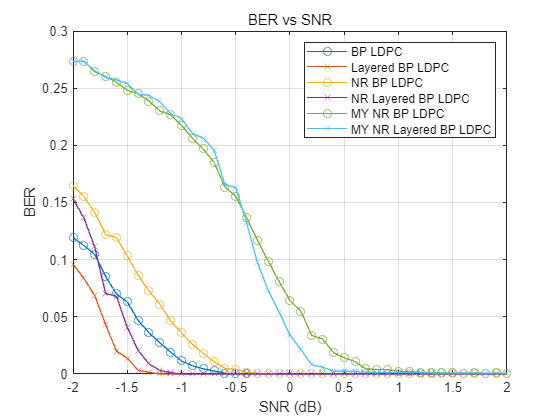

% 绘制 BER 曲线
figure;
plot(snr, ber_bp_list, '-o', 'DisplayName', 'BP LDPC');
hold on;
plot(snr, ber_layered_list, '-x', 'DisplayName', 'Layered BP LDPC');
hold on;
plot(snr, ber_nr_bp_list, '-o', 'DisplayName', 'NR BP LDPC');
hold on;
plot(snr, ber_nr_layered_list, '-x', 'DisplayName', 'NR Layered BP LDPC');
hold on;
plot(snr, ber_my_nr_bp_list, '-o', 'DisplayName', 'MY NR BP LDPC');
hold on;
plot(snr, ber_my_nr_layered_list, '-x', 'DisplayName', 'MY NR Layered BP LDPC');
xlabel('SNR (dB)');
ylabel('BER');
title('BER vs SNR');
legend;
grid on;

*Copyright 2021-2022 The MathWorks, Inc.*